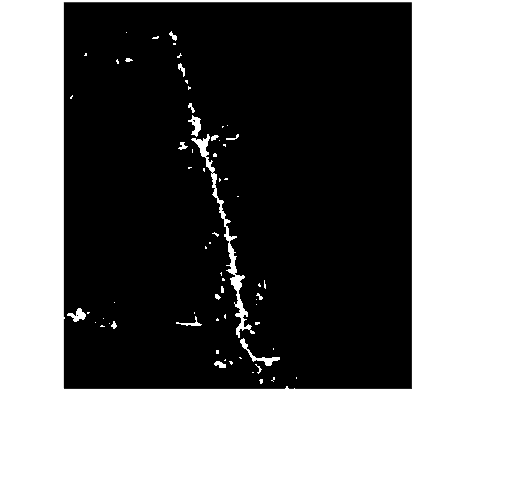

image = zeros(5, 800, 720, 3);
BW = zeros(5, 800, 720);
image(1,:,:,:) = imread("imageSeries1_year2000.jpg");
image(2,:,:,:) = imread("imageSeries1_year2004.jpg");
image(3,:,:,:) = imread("imageSeries1_year2008.jpg");
image(4,:,:,:) = imread("imageSeries1_year2012.jpg");
image(5,:,:,:) = imread("imageSeries1_year2016.jpg");
image = uint8(image);
hold on;
for i = 1:5
    currentRGBImage = squeeze(image(i,:,:,:));
   
    %BW(i,:,:) = getMask(currentRGBImage);
    %currentBW = squeeze(BW(i,:,:));
    BW(i, :, :) = getMask(currentRGBImage);
%     imshow(currentRGBImage)
%     imshow(squeeze(BW(i,:,:)))
end
imshow(squeeze(BW(1,:,:)))

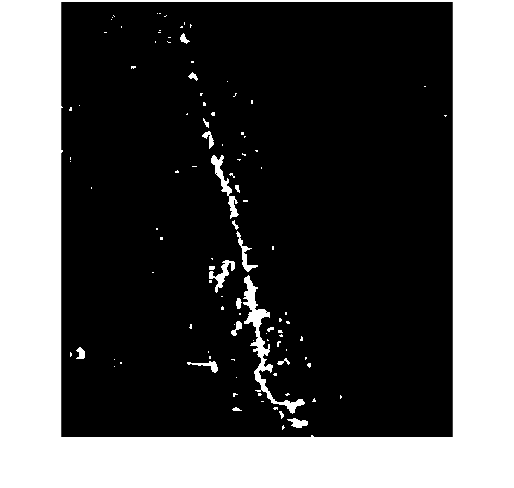

imshow(squeeze(BW(2,:,:)))

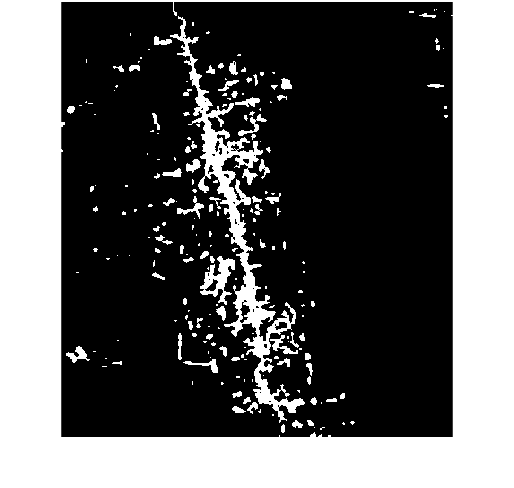

imshow(squeeze(BW(3,:,:)))

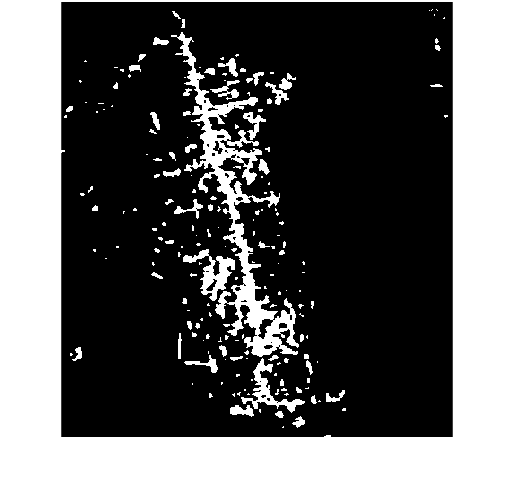

imshow(squeeze(BW(4,:,:)))

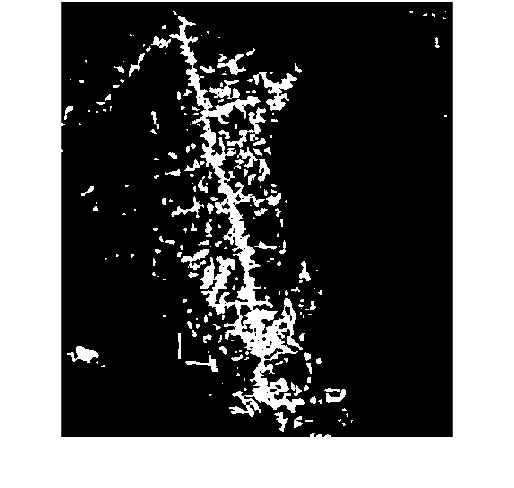

imshow(squeeze(BW(5,:,:)))


% year2000 = imread("imageSeries1_year2000.jpg");
% imshow(image(1))
% [BW2000, maskedRGBImage] = getMask(year2000);
% imshow(BW2000);
% imshow(maskedRGBImage);
% numTotal = numel(BW);
% numWhite = nnz(BW); %white is deforestation
% percentDeforested = numWhite/numTota
% 

%totalArea = getArea(year2000);
%deforestedArea = percentDeforested*totalArea;

%gray = im2gray(year2000);
% grayAdjust = imadjust(gray);
% imshow(grayAdjust)
% imshow(gray)
% imhist(grayAdjust)
% imhist(gray)
